# HW 15 - Numerical Integration

## Prob 1 - Numerical Integration

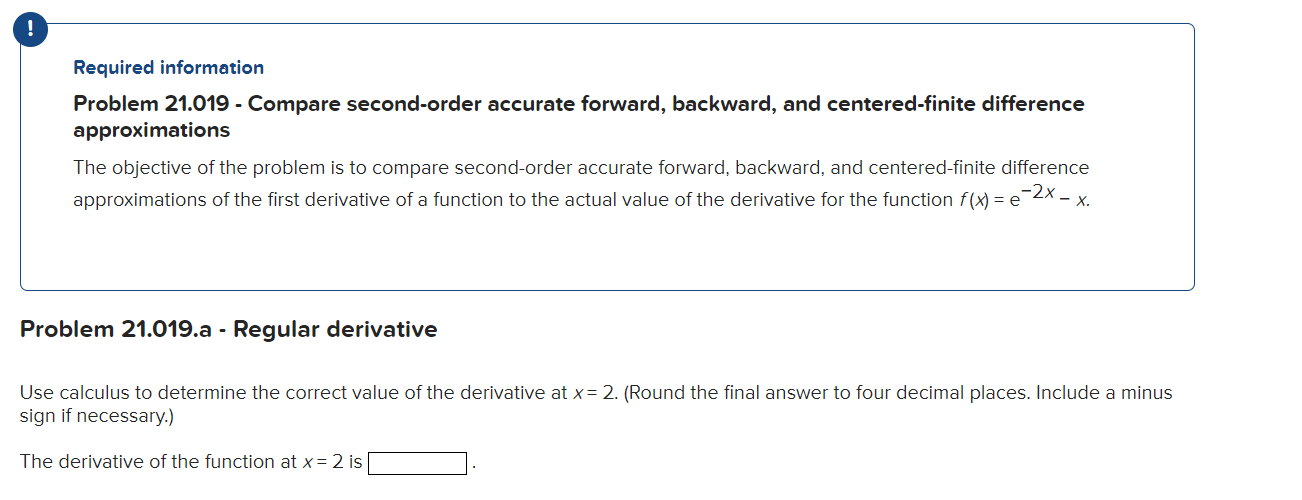

% Calculus
f = @(x) exp(-2*x) - x;
fp = @(x) -2*exp(-2*x) - 1;
fpp = @(x) 4*exp(-2*x);
fp(2)

ans = -1.0366


% diff
syms x
f_x = exp(-2*x) - x;
fp_x = diff(f_x)

$$fp\_x = -2\,{\mathrm{e}}^{-2\,x}-1$$

fpp_x = diff(fp_x)

$$fpp\_x = 4\,{\mathrm{e}}^{-2\,x}$$

double(subs(fp_x, x, 2))

ans = -1.0366


% rombdiff
help rombdiff

  romberg: Romberg integration quadrature
    [d,ea,iter]=rombdiff(func,x,es,maxit,varargin)
  Romberg differentiation.
  input:
    func = name of function to be integrated
    es = desired relative error (default = 0.000001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by func
  output:
    d = integral estimate
    ea = approximate relative error (%)
    iter = number of iterations



[d,ea,iter]=rombdiff(f,2)

d = -1.0366

ea = 7.4050e-07

iter = 4

## Prob 2

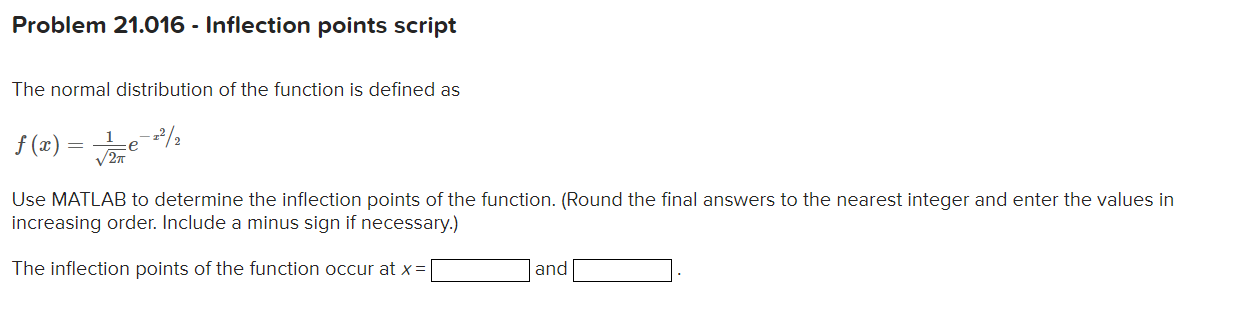

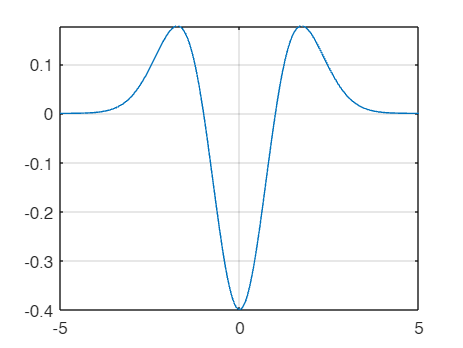

% inflection points = when 2nd deriv = 0
syms x
f = 1/sqrt(2*pi)*exp(-x.^2/2);
fp = diff(f);
fpp = diff(fp);
fpp_fun = matlabFunction(fpp); % @(x)
fplot(fpp); grid

fzero(fpp_fun,0.5)

ans = 1

fzero(fpp_fun,-2)

ans = -1


% Better way:
f = 1/sqrt(2*pi)*exp(-x^2/2);
f2 = diff(f,2); % 2nd deriv*****
solve(f2==0,x)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$